% Optimal oordination of DOCR (67 NEUTRAL)  
% Paulo M. De Oliveira, pm.deoliveiradejes@uniandes.edu.co
% https://power.uniandes.edu.co/
% Los Andes University
% First version: July 15, 2020 
% Runs the optimization problem for only one Rf
clc
close all
clear all 
global Dmin Co nr Rg Rf Ipx S3a S3b S3c pf3a pf3b pf3c  k1 k2 k3 Mmax
time00=cputime;

## Case study

LoadDatabase; %Load the Three-bus test case
neval=1000; %number of evaluations in the verification stage

## Fault resistance in Ohms

Rf=000010.00000001;%

Ipx=0.05; %Pick-up currents in all relays
Mmax=30.0; % Maximum allowable multiplier  (Icc/Ip)

 disp('Optimal 67N Directional Overcurrent Relays Coordination Problem.')

Optimal 67N Directional Overcurrent Relays Coordination Problem.


 disp('Version 1.1 (c) 2020')

Version 1.1 (c) 2020


 disp('Power and Energy Group - https://power.uniandes.edu.co/')

Power and Energy Group - https://power.uniandes.edu.co/


 disp('Universidad de los Andes, Colombia')

Universidad de los Andes, Colombia


 disp('*************************************************************')

*************************************************************


## Build the relay coordination model (B matrix)

      iter=1;     
for kk=1:n
[index2]=model_setup_OpenDSS(L(kk,:));%runs the OpenDSS engine using the COM Intrerface
index(:,09)=index2(:,1);
index(:,10)=index2(:,2);
index(:,17)=index2(:,3);
index(:,18)=index2(:,4);
index(:,13)=index2(:,5);
index(:,14)=index2(:,6);

## Normal configuration constraints

if kk==1
    for k=1:length(index(:,14))
         if abs(index(k,17)-index(k,18)) < qmax
              if index(k,13) > 0
             if index(k,14) > 0
Aneq(iter,index(k,3))=-index(k,13);
Aneq(iter,index(k,1))=index(k,14);
Imain(iter,1)=index(k,13-4);
Iback(iter,1)=index(k,14-4);
iter=iter+1;
end
end
end
end
else
for k=1:length(index(:,14))     

     if abs(index(k,17)-index(k,18)) < qmax
          if index(k,13) > 0
         if index(k,14) > 0
Aneq(iter,index(k,3))=-index(k,13);
Aneq(iter,index(k,1))=index(k,14);
Imain(iter,1)=index(k,13-4);
Iback(iter,1)=index(k,14-4);
 iter=iter+1;
         end
          end
          end
 end
end 
mm=length(index(:,14));

## Objective function: only primary times for near faults

jj=1;
for i=1:nr
   jj=find(index(:,3)==i);
   fx(kk,i)=index(jj(1),13);
end
end    
% Ezzanine objective funtion. only near faults
for k=1:2:nr  
fe(k)=fx(1,k);
end
for k=2:2:nr  
fe(k)=fx(2,k);
end

## SPROT objective funtion. all faults

for k=1:nr
 f(k)=.5*fx(1,k)+.5*fx(2,k);
end

## Setup the optimization problem

x0=zeros(nr,1); %startup
fprintf('Fault resistance: %6.2f ohms \n',Rf)

Fault resistance:  10.00 ohms 


fprintf('Ground pole resistance: %6.2f ohms \n',Rg)

Ground pole resistance:   0.00 ohms 


fprintf('Load Bus3 phase a: %6.2f MVA pf= %6.2f lag\n',S3a,pf3a)

Load Bus3 phase a:   0.00 MVA pf=   0.80 lag


fprintf('Load Bus3 phase b: %6.2f MVA pf= %6.2f lag\n',S3b,pf3b)

Load Bus3 phase b:   0.00 MVA pf=   0.80 lag


fprintf('Load Bus3 phase c: %6.2f MVA pf= %6.2f lag\n',S3c,pf3c)

Load Bus3 phase c:   0.00 MVA pf=   0.80 lag


fprintf('Pick-up current in all relays: %6.2f A \n',Ipx*1000)

Pick-up current in all relays:  50.00 A 


fprintf('Minimum Time Dial setting: %6.2f \n',Dmin)

Minimum Time Dial setting:   0.10 


fprintf('Maximum Time Dial setting: unbounded\n')

Maximum Time Dial setting: unbounded


fprintf('Coordination interval: %6.2f s\n',Co)

Coordination interval:   0.20 s


fprintf('Relay curve parameters %6.2f %6.2f %6.2f\n',k1,k2,k3)

Relay curve parameters   0.14   0.02  -1.00


fprintf('Modelling with %d faults per line: near-end far-end faults.\n',n)

Modelling with 2 faults per line: near-end far-end faults.


fprintf('****** Sensitibity and Selectivity Analisis *****************\n')

****** Sensitibity and Selectivity Analisis *****************


fprintf('Number of fault currents to be detected: %8.0f  \n',mm*n)

Number of fault currents to be detected:       12  


fprintf('Number of detected fault currents:    %6.0f  \n',length(Aneq(:,1)))

Number of detected fault currents:         7  


fprintf('Number of nondetected fault currents: %6.0f \n',mm*n-length(Aneq(:,1)));

Number of nondetected fault currents:      5 


fprintf('Percentage of detected faults currents: %6.2f %% \n',100*length(Aneq(:,1))/(mm*n))

Percentage of detected faults currents:  58.33 % 


elapsedtime00=cputime-time00;
fprintf('Elapsed modelling time:       %6.2f s \n',elapsedtime00)

Elapsed modelling time:         0.73 s 


fprintf('*************************************************************\n')

*************************************************************


% LP solver
time0=cputime;
LB=ones(nr,1)*Dmin;
UB=[]; 
Aeq=[];
beq=[];
bneq=ones(length(Aneq(:,1)),1)*Co;
disp(' ')

disp('  ')

disp('Optimizing. Please wait...! ')

Optimizing. Please wait...! 


% SOLVING the Optimization problem: min f st. Aneq > bneq
options = optimoptions('linprog','Algorithm','interior-point','display','off');
[x,FVAL,EXITFLAG]=linprog(f,-Aneq,-bneq,Aeq,beq,LB,UB,x0,options);
elapsedtime=cputime-time0;
disp('**** Optimization Results ************************************') 

**** Optimization Results ************************************


if EXITFLAG < 0
fprintf('DO NOT CONVERGE')    
else  
fprintf('Number of unknowns: %d \n',nr)
fprintf('Number of constraints (selectivity): %d \n',length(Aneq(:,1)))
fprintf('Number of constraints (time dial limits): %d \n',nr)
fprintf('Ezzadinne Objective Function (only near faults): %7.4f s\n',fe*x )
fprintf('System Primary Relay Operation Time: %7.4f s\n',FVAL)
for k=1:nr
fprintf('Optimal TDS Relay %d: %7.4f\n',k,x(k))
end
fprintf('Elapsed optimization time: %6.2f s \n',elapsedtime)
fprintf('*************************************************************\n')

Number of unknowns: 6 


Number of constraints (selectivity): 7 


Number of constraints (time dial limits): 6 


Ezzadinne Objective Function (only near faults):  1.7223 s


System Primary Relay Operation Time:  2.3222 s


Optimal TDS Relay 1:  0.1617
Optimal TDS Relay 2:  0.1282
Optimal TDS Relay 3:  0.1457
Optimal TDS Relay 4:  0.1572
Optimal TDS Relay 5:  0.1247
Optimal TDS Relay 6:  0.1484


Elapsed optimization time:   2.17 s 


*************************************************************


## investigating the quality of the solution

fprintf('Verifying the quality of the solution with %d random faults\n',neval)

Verifying the quality of the solution with 1000 random faults


disp('Simulating. Please wait...! ')

Simulating. Please wait...! 


time000=cputime;
[mtpr,minminIsep,tpr,S,Nxx,DVs] = runchecker_OpenDSS(x,neval,qmax,Rf);

Progress: 25%, 50%, 75%, 100%


elapsedtime000=cputime-time000;
%  
S2=[S(:)]';
kkk=0;jjj=0;ki=0;
for k=1:length(S2)
if S2(k) < 2
kkk=kkk+1;       
SepI(kkk)= S2(k) ;
end
if S2(k) < Co
ki=ki+1;
S2(k);
end
end
sel=(1-ki/length(S2))*100;%selectivity level
disp('**** Simulation Results (Verification)****')

**** Simulation Results (Verification)****


fprintf('Number of fault currents to be detected:   %8.0f  \n',mm*neval)

Number of fault currents to be detected:       6000  


fprintf('Number of detected fault currents:         %8.0f  \n',Nxx)

Number of detected fault currents:             4884  


fprintf('Number of nondetected fault currents:      %8.0f  \n',mm*neval-Nxx)

Number of nondetected fault currents:          1116  


fprintf('Percentage of detected fault currentss:    %5.2f  %% \n',100*Nxx/(mm*neval))

Percentage of detected fault currentss:    81.40  % 


fprintf('Mean Operation Times calc with resulting TDSs:    %7.4f\n',mtpr)

Mean Operation Times calc with resulting TDSs:     2.0399


fprintf('StdDev Operation Times calc with resulting TDSs:  %7.4f\n',std(tpr))

StdDev Operation Times calc with resulting TDSs:   0.0599


fprintf('Verifying if minimum calculated separation time %5.4f is higher than the coordination time C=%7.4f\n',minminIsep,Co) 

Verifying if minimum calculated separation time 0.1998 is higher than the coordination time C= 0.2000


fprintf('Result: %5.4f %% of the faults accomplishes the allowable coordination interval C=%7.4f\n',sel,Co) 

Result: 99.9795 % of the faults accomplishes the allowable coordination interval C= 0.2000


%fprintf('Elapsed simulation time: %6.2f s \n',elapsedtime000)
disp('******************************************')

******************************************


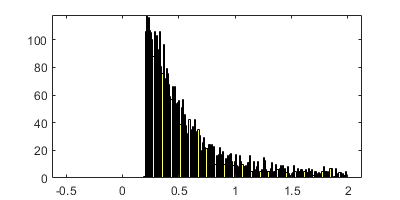

close all
figure('name','Separation Times Histogram (s)','position',[0, 300, 400, 200])
xbins = -0.50:0.01:2;
% Separation Times Histogram
h=histogram(SepI,xbins,'FaceColor','yellow');
set(gcf,'color','w')

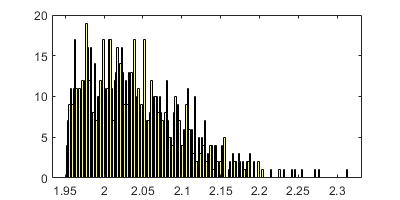

counts = h.Values';
figure('name','SROT Histogram (s)','position',[0, 0, 400, 200])
% SROT Histogram
h=histogram(tpr,200,'FaceColor','yellow');
set(gcf,'color','w')

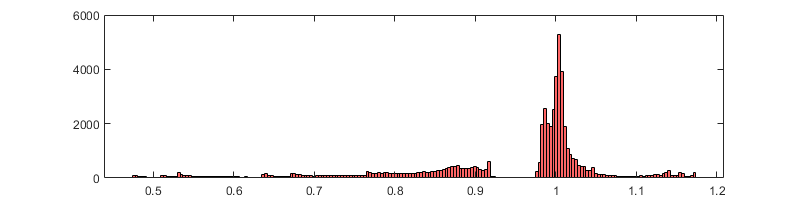

counts = h.Values;
figure('name','Voltage Histogram (s)','position',[0, 100, 800, 200])
% DVs Histogram
h=histogram(DVs,200,'FaceColor','red');
set(gcf,'color','w')

counts = h.Values;
end